rga analysis

load('Assignment_Data_SC42145.mat');
G = tf(FWT(1:2,1:2));

%evaluate at
freq = 0.8*pi;
freq = 0;

G_s = evalfr(G, freq);
RGA_0 = G_s.*inv(G_s)';


[U,S,V] = svd(RGA_0);
lat_ = matrix2latex(RGA_0)+"="+matrix2latex(U)+matrix2latex(S)+matrix2latex(V);
disp(lat_+"^T");

  \begin{bmatrix}
   -0.655 &  1.655 \cr
    1.655 & -0.655
  \end{bmatrix}
=  \begin{bmatrix}
   -0.707 &  0.707 \cr
    0.707 &  0.707
  \end{bmatrix}
  \begin{bmatrix}
    2.311 &  0.000 \cr
    0.000 &  1.000
  \end{bmatrix}
  \begin{bmatrix}
    0.707 &  0.707 \cr
   -0.707 &  0.707
  \end{bmatrix}
^T



max_sigma_0 = max(diag(S));
min_sigma_0 = min(diag(S));
gamma_0 = max_sigma_0/min_sigma_0

gamma_0 = 2.3108

poles and zero calculation

poles = pole(FWT)

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


disp("="+matrix2latex(poles));

=  \begin{bmatrix}
   -0.083+3.294i \cr
   -0.083-3.294i \cr
   -0.410+0.000i \cr
   -0.011+0.202i \cr
   -0.011-0.202i
  \end{bmatrix}



zeros_ = tzero(FWT)

zeros_ =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i


disp("="+matrix2latex(zeros_));

=  \begin{bmatrix}
   -0.008+1.236i \cr
   -0.008-1.236i
  \end{bmatrix}



designing W_p11, generalized plant

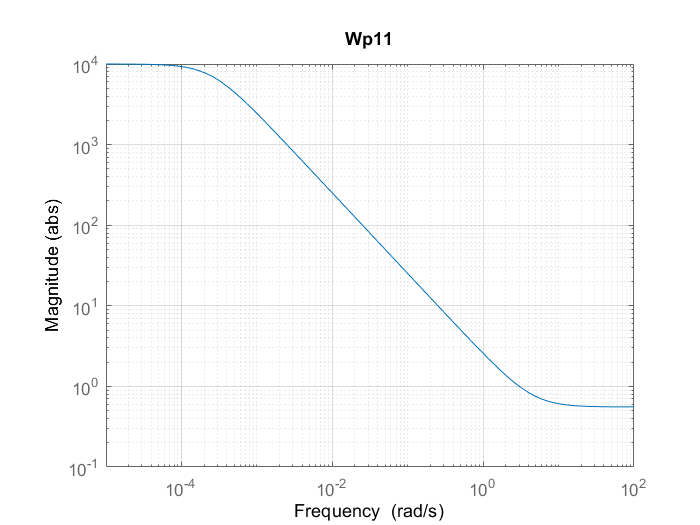

% obtain plant
MIMO_ss = minreal(tf(FWT(1:2,1:2)));


% build W matrices and generalized plant
Wp11 = tf([1/1.8, 0.8*pi], [1, 0.8*pi*1e-4]);
Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);
%plotoptions = bodeoptions('')
figure()
bodemag(Wp11)
title('Wp11'); grid on
setoptions(gcr,'MagUnits','abs', 'MagScale', 'log');

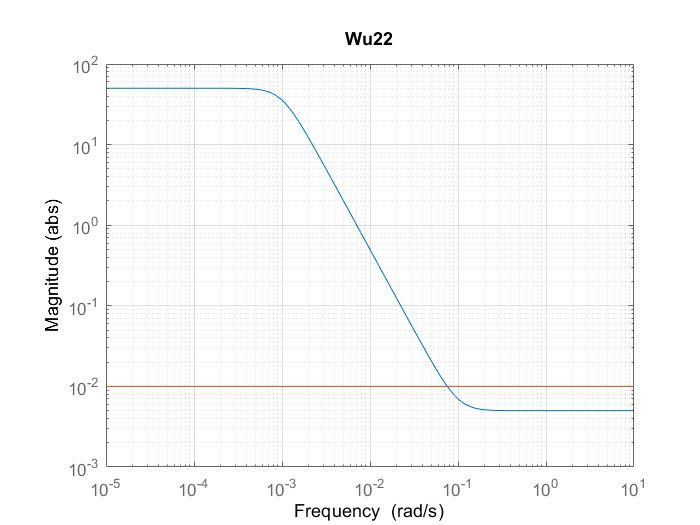


figure()
bodemag(Wu22)
title('Wu22'); grid on
hold on
bodemag(tf([0.01]))
setoptions(gcr,'MagUnits','abs', 'MagScale', 'log');


Wp = [Wp11 0; 0 0.2];
Wu = [0.01 0; 0 Wu22];
P11=[Wp; zeros(2,2)]; P12=[Wp*MIMO_ss; Wu]; P21=eye(2); P22=MIMO_ss;
P = [P11 P12; P21 P22];

% H-infinity norm synthesis
[K, CL, gamma,syn_info] = hinfsyn(P, 2, 2); %2 inputs, 2 outputs

H_inf_norm_CL = gamma

H_inf_norm_CL = 0.7993


closed_loop = minreal(feedback(MIMO_ss, -K));

27 states removed.


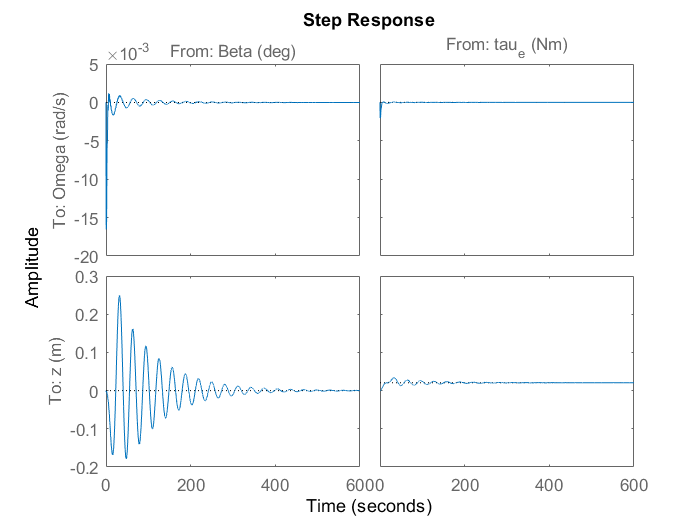

figure()
step(closed_loop)



%L_ref = feedback(MIMO_ss, K, [1,2], [1,2], -1);
%L_dist = feedback(FWT, K, [1,2], [1,2], -1);